# CIE 425 - Information Theory and Coding 

**Final Project - H264 Video Compression**

Fall 2022

**Team Members:**

Youssef Islam Elshabrawy          201-900-667

Amr Ahmed Elmasry 	            201-901-202

Ahmed Mohamed Ibrahem         201-902-227

## **1. Video Encoder**

This function converts any supported MATLAB video into H.264 binary stream of bits.

clc; clear;
% Encode
[code, dict,Quant, Ls, fps, L, W] = MPEG_Encode("xylophone.mp4", 1);
code

code =      0     0     0     0     0     1     1     1     1     0     1     1     0     0     0     0     1     1     0     1     1     0     0     0     1     0     0     1     1     0     1     1     0     0     0     0     0     1     1     1     1     1     1     0     0     1     0     1     0     1


### **Function Parameters**

`The function Takes ``3 input arguments``:`

- **Path/name** of the file to be converted (or a matlab prebuilt video like “xylophone.mp4”.)

- **Quantization Level**: 1 for low, and 2 for high quantization.

- [Optional] Number of frames to be encoded.

`It returns ``7 outputs``:`

- The **binary encoded** frames and motion vectors.

code

code =      0     0     0     0     0     1     1     1     1     0     1     1     0     0     0     0     1     1     0     1     1     0     0     0     1     0     0     1     1     0     1     1     0     0     0     0     0     1     1     1     1     1     1     0     0     1     0     1     0     1


- The **huffman dictionary** (cood-book) for this code.

dict(1:5,:)

ans = 5×2 cell array
    {[-175]}    {[    0 0 0 0 0 1 1 1 1 0 1 0 1 0 1 0 0 0 0 1 0]}
    {[-174]}    {[  0 1 0 0 1 1 1 1 1 0 0 1 1 0 0 1 0 1 1 0 1 1]}
    {[-167]}    {[0 1 0 0 1 1 1 1 1 0 0 1 1 0 0 1 0 1 1 0 1 0 0]}
    {[-165]}    {[0 1 0 0 1 1 1 1 1 0 0 1 1 0 0 1 0 1 1 0 1 0 1]}
    {[-164]}    {[    0 1 0 0 1 1 1 0 1 1 0 1 1 1 0 0 0 0 1 0 1]}


- The **quantization level** (again)

Quant

Quant = 1

- The **Length of Streams**: It is a very important design parameter and it is an array holding the length of the frame followed by the length of its motion vector. Example:

Ls

Ls =       154216           4      159892        2103      161531        2103      162109        2111      163427        2110      165010        2110      167379        2124      167405        2131      169077        2129      167416        2116      156108           4      161697        2106      162229        2101      162085        2114      164800        2121      162828        2126      162353        2124      163559        2130      164664        2151      164363        2152      157881           4      158170        2106      159076        2105      161463        2106      162892        2113


**Column 1** represents the **length of frame 1**, **column 2** is the** length of Motion Vector 1** (which is in this case 4 bits that will be ignored as frame 1 is an I-frame). Columns 3, and 4 represent the length of frame 2 and motion vector 2 respectively, and so on.

- The** Framerate** of the video which is extracted from the video object to be used in the decoder.

fps

fps = 30

- The** Length** of the frame

L

L = 240

- The **Width** of the frame

W

W = 320

### Compression Ratio

For the Low Quantization:

141 is the number of frames in video, and 8 is log2(256)

OriginalSize = L * W * 8 * 141; 
CR = OriginalSize/length(code)

CR = 3.7767

For the High Quantization:

[code_high, dict_high, Quant_high, Ls_high, fps2, L2, W2] = MPEG_Encode("xylophone.mp4", 2);
CR_high = OriginalSize/length(code_high)

CR_high = 11.3999

## **2. Video Decoder**

This function reconstructs code from the encoder function into a grayscale version of the input video.

% Decode
matrix = MPEG_Decode(code, dict, Quant,Ls, fps,L, W,"myOutput_H")

matrix = matrix(:,:,1) =

    54    53    52    52    52    51    48    46    43    42    42    41    39    38    38    37    38    38    38    38    38    38    38    38    36    36    37    38    38    39    40    40    42    39    36    34    34    35    35    34    33    33    32    32    33    35    38    39    40    40    40    41    41    42    42    42    43    43    43    43    43    43    43    43    45    43    42    41    41    39    35    32    24    27    39    56    65    67    70    75   106   110   121   137   151   160   166   170   167   168   167   167   168   163   163   171   197   195   171    41    40    29    37    24    35    36    37    38    39    40    41    41    44    44    44    44    44    44    44    44    44    44    44    43    43    43    43    42    42    43    43    43    44    44    44    44    46    47    47    47    48    48    48    48    50    51    51    52    52    51    51    50    49    49    49    49    49    49    49    49    49    49  

### **Function Parameters**

`The function Takes 8`` input arguments``:`

- **Encoded Video **bits to be decoded.

- **Huffman Dictionary** used in encoding 

- **Quantization Variable** (1 = low, 2 = high)

- The **Length of Streams** specified in the encoder

- The **frame rate** to be used in writing the output video

- **Length** of original video

- **Width** of original video

- [optional] **Output file name** to write video in

`It returns 1`` output``: Which is the 3D matrix of the frames`

matrix

matrix = matrix(:,:,1) =

    54    53    52    52    52    51    48    46    43    42    42    41    39    38    38    37    38    38    38    38    38    38    38    38    36    36    37    38    38    39    40    40    42    39    36    34    34    35    35    34    33    33    32    32    33    35    38    39    40    40    40    41    41    42    42    42    43    43    43    43    43    43    43    43    45    43    42    41    41    39    35    32    24    27    39    56    65    67    70    75   106   110   121   137   151   160   166   170   167   168   167   167   168   163   163   171   197   195   171    41    40    29    37    24    35    36    37    38    39    40    41    41    44    44    44    44    44    44    44    44    44    44    44    43    43    43    43    42    42    43    43    43    44    44    44    44    46    47    47    47    48    48    48    48    50    51    51    52    52    51    51    50    49    49    49    49    49    49    49    49    49    49  

## Results

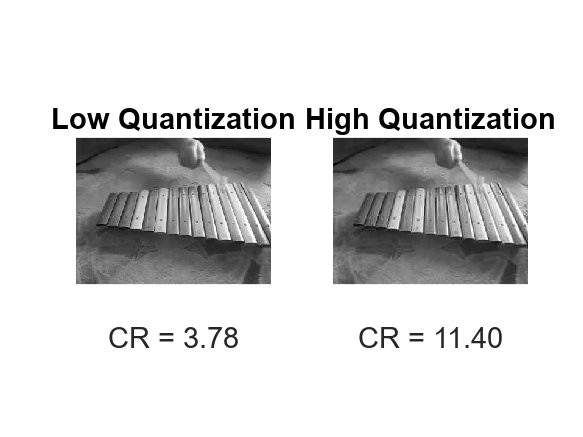

matrix_high = MPEG_Decode(code_high, dict_high, Quant_high,Ls_high, fps2,L2, W2,"myOutput_High");
highFrame = uint8(matrix_high(:,:,141));
lowFrame = uint8(matrix(:,:,141));
figure
subplot(121); imshow(lowFrame);title('Low Quantization');xlabel(sprintf('CR = %.2f', CR))
subplot(122); imshow(highFrame);title('High Quantization');xlabel(sprintf('CR = %.2f', CR_high))

We tried the functions on a larger video with multiple frame changes to test our compression, and the results were as we expected!

[Videos Link!](https://drive.google.com/drive/folders/1IozzEp1Xvqb2I2MYSoLV4cp8tCIGd7zG?usp=share_link)

cr7_out.mp3 is compressed with compression ratio:

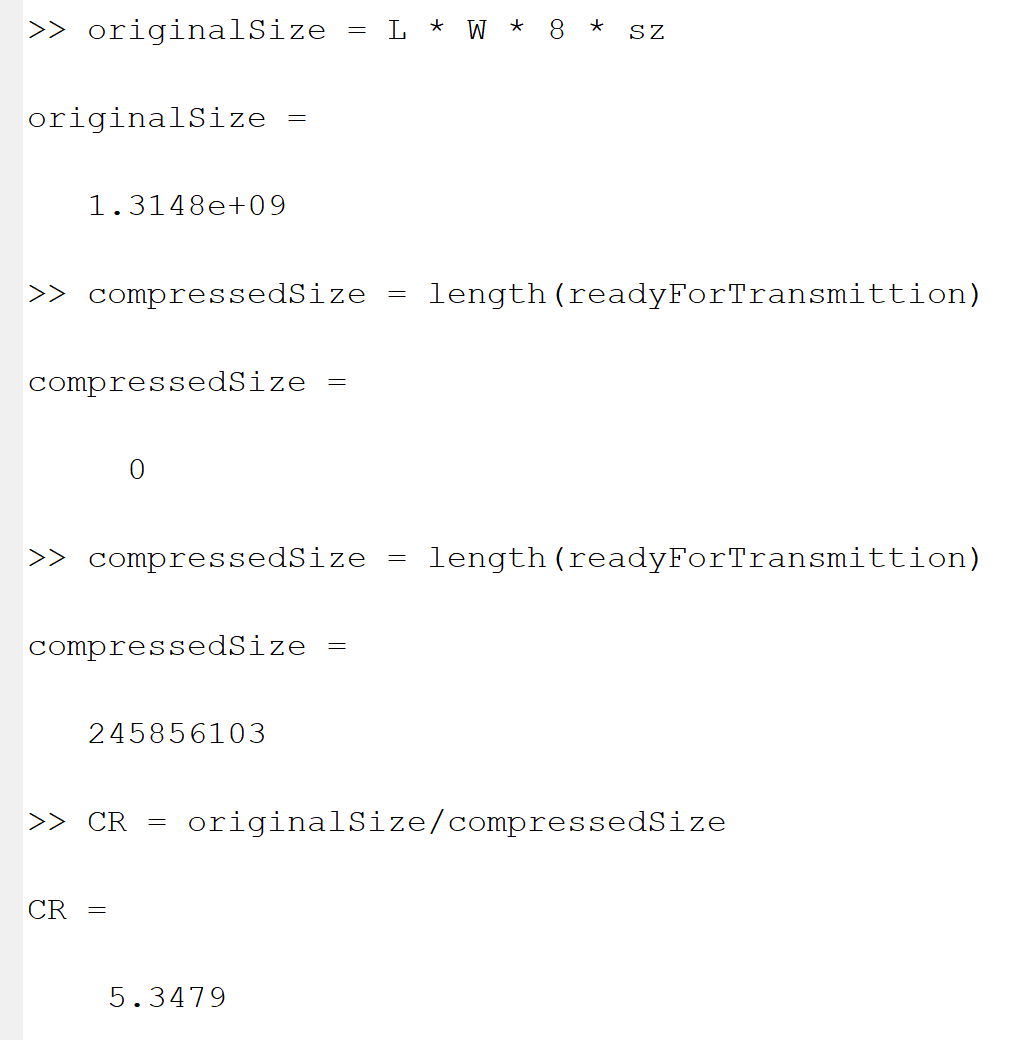 **CR = 5.3479**

## RGB Encoding 😲

[code_rgb, dict_rgb,Quant_rgb, Ls_rgb, fps_rgb, L_rgb, W_rgb] = RGB_MPEG_Encode("cr7.mp4", 1);

RGB_MPEG_Decode(code_rgb, dict_rgb, Quant_rgb,Ls_rgb, fps_rgb,L_rgb, W_rgb,"cr7_out_RGB");